# Packing Analysis

## Gregory Glance & Mauro Lozano 07/20/2022

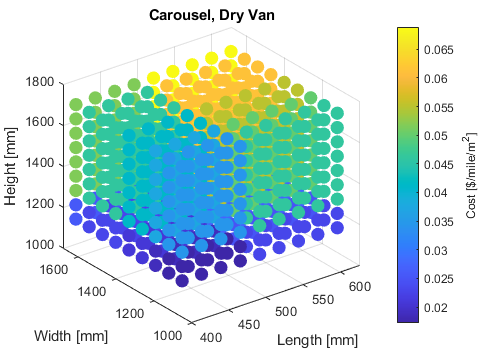

Dims w/ Min. Cost 
Cost [$/mile/m^2]: 0.017219 
Units Per truck:   96 
Blocks [LxWxH]:    4 x 12 x 2 
Volume Eff. [%]:   74.572432 - 95.331274 
Mass eff. [%]:     68.461178 

L [mm]:            417.376000 - 495.634000 
W [mm]:            1119.999995 - 1189.999995 
H [mm]:            1119.999995 - 1189.999995 
----------------------------------------------------------


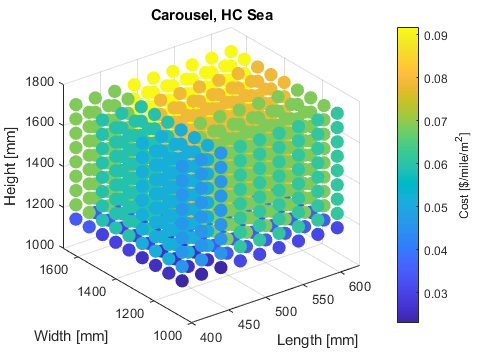

Dims w/ Min. Cost 
Cost [$/mile/m^2]: 0.022959 
Units Per truck:   72 
Blocks [LxWxH]:    4 x 9 x 2 
Volume Eff. [%]:   81.446886 - 89.535667 
Mass eff. [%]:     39.837323 

L [mm]:            417.376000 - 469.548000 
W [mm]:            1119.999995 
H [mm]:            1119.999995 
----------------------------------------------------------


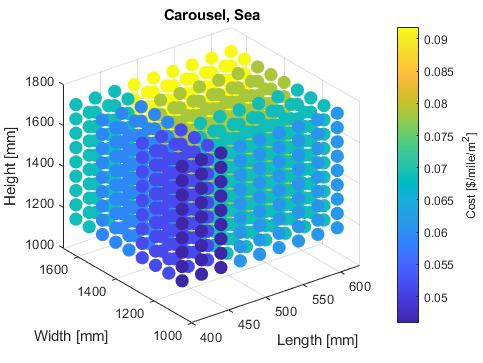

Dims w/ Min. Cost 
Cost [$/mile/m^2]: 0.045918 
Units Per truck:   36 
Blocks [LxWxH]:    4 x 9 x 1 
Volume Eff. [%]:   45.922180 - 72.535968 
Mass eff. [%]:     19.254706 

L [mm]:            417.376000 - 469.548000 
W [mm]:            1119.999995 
H [mm]:            1119.999995 - 1679.999993 
----------------------------------------------------------


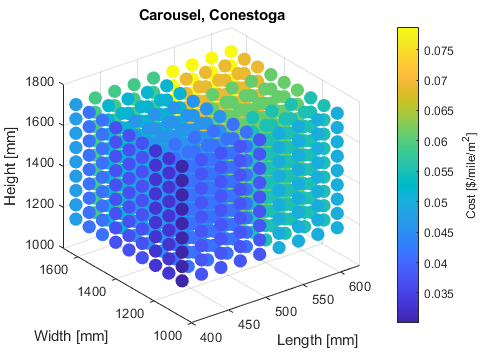

Dims w/ Min. Cost 
Cost [$/mile/m^2]: 0.030056 
Units Per truck:   55 
Blocks [LxWxH]:    5 x 11 x 1 
Volume Eff. [%]:   48.862347 - 70.207522 
Mass eff. [%]:     33.264216 

L [mm]:            417.376000 
W [mm]:            1119.999995 
H [mm]:            1119.999995 - 1679.999993 
----------------------------------------------------------


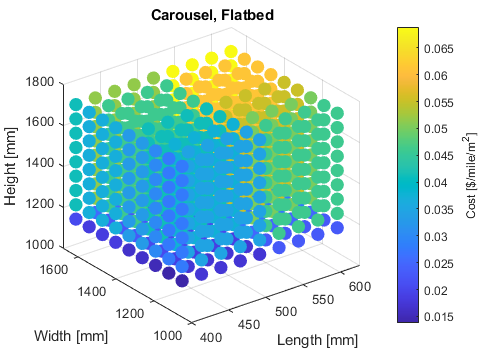

Dims w/ Min. Cost 
Cost [$/mile/m^2]: 0.013775 
Units Per truck:   120 
Blocks [LxWxH]:    5 x 12 x 2 
Volume Eff. [%]:   92.765000 - 97.868387 
Mass eff. [%]:     68.040442 

L [mm]:            417.376000 
W [mm]:            1119.999995 - 1189.999995 
H [mm]:            1119.999995 
----------------------------------------------------------


%{
Objective: visualize how packing density affects cost of shipping

This program creates a range of widths, depths, and heights given initial
medians. Every combination of W x D x H is created and then--using
constants for packaging and shipping container dimensions--the total
shipping dimensions are determined for every W x D x H combination.
The number of containers that can fit per W x D x H of the shipping container 
is calculated. The cost of shipping each m^2 of mirror is calculated and 
then visualized. Give a consise output of dimensions: best range for cost
and best range for volume efficiency.

TO DO:
- Subtract L and W from the Home Plate area    
- Lay the home plate flat (Design different packaging units for Home Plate)
- Make more accurate mass calculation based on larger or smaller dimensions
%}
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc
clear all

% Inputs
% L [in], W(D) [in], H [in], [kg]
HelioStat_dims = [
    %["7.6", "47.4", "53.7", "39.51", "Home Plate (Single)"];
    %["7.6", "89.5", "53.7", "62.62", "Home Plate (Dual)"];
    %["10.7826772", "47.2441", "62.99213", "35", "Linear Actuator"];
    ["20.5401575", "55.11811", "55.11811", "35", "Carousel"]
    %["1.1875", "63", "47.25", "31.75", "Gen4 HelioStat"]
    %["7.6", "23.622", "31.4961", "35", "1/2 mirror line, 1/4 float line"]; 
    %["7.6", "47.2441", "62.9921", "35", "1 x mirror line, 1/2 float line"]; 
    %["7.6", "47.2441", "78.7402", "35", "1 x mirror line, 2/3 & 1/3"];
    %["7.6", "47.2441", "42.007874", "35", "1 x mirror line, 1/3 float line"]
    ];

orig = false; % show data for original dimensions?
lim_m = false; % limit the mass efficiency to 100%?
ideal = true; % display the ideal dimension data?


% L [in], W(D) [in], H [in], [lbs]
Van_dims = [
    ["98", "636", "108", "45000", "Dry Van"];
    ["92", "474", "106", "58000", "HC Sea"];
    ["92", "474", "94", "60000", "Sea"];
    ["102", "576", "98", "45000", "Conestoga"];
    ["102", "636", "102", "48000", "Flatbed"]; 
    %["102", "480", "120", "15000", "Hot Shot"]
    ];

Packaging = [2, 6, 6.375, 7, 975]; % Sp [in], W [in], H[in], L [in], weight [lbs]

eff_dim_calc(HelioStat_dims, Van_dims, Packaging, orig, lim_m, ideal);

## full_fact() Function

function des_mat= full_fact(varargin)

for i=1:nargin
    levels(i)=length(varargin{i});
    % Converting row vector to column vector
    if size(varargin{i},1)==1,varargin{i}=varargin{i}';end
end
% Check number of variables and levels of each variable
if nargin<2
    error 'Minimum 2 variables are required'
end
if ~all(levels >1)
    error 'Each variables should have minimum 2 levels'
end
% Total number of design points
total=prod(levels);
%Initilization of output matrix
des_mat=zeros(0,1);
% Loop for full factorial points
for i=1:nargin
    if i~=1 && i~=nargin
        temp=zeros(0,1);
        for j=1:prod(levels(1:i-1))
            temp1=repmat(varargin{i},prod(levels(i+1:end)),1);
            temp1=sortrows(temp1);
            temp=[temp; temp1];
        end
    elseif i==nargin
        temp=repmat(varargin{i},total/levels(i),1);
    else
        temp=repmat(varargin{i},total/levels(i),1);
        temp=sortrows(temp);
    end
    des_mat=[des_mat temp];
end

end

Helper Fucntions

% This function takes in a set of W x D x H dimensions and creates a 
% list of ranges for those dimensions and then creates all posisble 
% combintations of those dimensions/ranges.
function HelioStatFullFact = find_combos(HSdims)    
    low_bound = 0.8; % -20%
    upp_bound = 1.2; % +20%
    space = 0.05; % [in] ~= 0.00254m
    
    HelioStat_inputs.W = HSdims(1)*low_bound: HSdims(1)*space: HSdims(1)*upp_bound; % L [in]
    HelioStat_inputs.D = HSdims(2)*low_bound: HSdims(2)*space: HSdims(2)*upp_bound; % W [in]
    HelioStat_inputs.H = HSdims(3)*low_bound: HSdims(3)*space: HSdims(3)*upp_bound; % H [in]
    HelioStatFullFact = full_fact(HelioStat_inputs.W, HelioStat_inputs.D, HelioStat_inputs.H); % [in]
end


% This function graphs dimension data and color-coded based on coresponding
% cost to ship.
function graph_data(HSdims, DolPerM2, HS_dim, van)
    x = HSdims(:,1) .* 25.4; % in -> [mm]
    y = HSdims(:,2) .* 25.4; % in -> [mm]
    z = HSdims(:,3) .* 25.4; % in -> [mm]
    scatter3(x, y, z, 100, DolPerM2,'filled');
    cb = colorbar;
    colormap parula
    xlabel('Length [mm]')
    ylabel('Width [mm]')
    zlabel('Height [mm]')
    cb.Label.String = 'Cost [$/mile/m^2]';
    title(HS_dim(5) + ', ' + van.name)
end

% Given a list of dimensions, this fuction displays the ranges of these dimensions
function ideal_dims = disp_ideal_data(totals, og)
    ind_limM = totals.weights > 0;
    if totals.limM, ind_limM = totals.weights < 1; end

    ind = find(totals.costs == min(totals.costs(ind_limM)));
    temp_ideal_dims = totals.ori_HSDims(ind,:); % [in]
    ideal_dims = temp_ideal_dims * 25.4; % in -> [mm]
    maxUnits = max(totals.units(ind_limM));
    l_dims = min(ideal_dims);
    h_dims = max(ideal_dims);
    best_vol_eff = totals.vol_eff(ind);
    low_vol_eff = min(best_vol_eff) * 100;
    high_vol_eff = max(best_vol_eff) * 100;

    if og.ideal
        % Display various parameters based on ideal dimensions
        fprintf('Units Per truck:   %d \n', maxUnits);
        fprintf('Blocks [LxWxH]:    %d x %d x %d \n', totals.blocks(ind(1),1), totals.blocks(ind(1),2), totals.blocks(ind(1),3));
        
        if low_vol_eff == high_vol_eff, fprintf('Volume Eff. [%%]:   %f \n', low_vol_eff);
        else, fprintf('Volume Eff. [%%]:   %f - %f \n', low_vol_eff, high_vol_eff); end
        % fprintf('Max Vol. Eff. [%%]: %f \n', (max(totals.vol_eff)*100));
        % fprintf('HSplusP Max Dims [in]: %f, %f, %f \n', HSplusPdims(1), HSplusPdims(2), HSplusPdims(3));
        fprintf('Mass eff. [%%]:     %f \n\n', max(totals.weights(ind(1)))*100);
    
        if size(ideal_dims) == [1, 3]
            l_dims = ideal_dims;
            h_dims = ideal_dims;
        end
    
        if l_dims(1) == h_dims(1), fprintf('L [mm]:            %f \n', l_dims(1)); 
        else, fprintf('L [mm]:            %f - %f \n', l_dims(1), h_dims(1)); end
    
        if l_dims(2) == h_dims(2), fprintf('W [mm]:            %f \n', l_dims(2)); 
        else, fprintf('W [mm]:            %f - %f \n', l_dims(2), h_dims(2)); end
    
        if l_dims(3) == h_dims(3), fprintf('H [mm]:            %f \n', l_dims(3)); 
        else, fprintf('H [mm]:            %f - %f \n', l_dims(3), h_dims(3)); end
    
        fprintf('----------------------------------------------------------\n');
    end

    if og.bool
        kg2lbs = 2.205;
        ogDta = calc_most_units(og.vanDims, og.dims(1:3), og.pack, og.dims(4)*kg2lbs);
        og_cost = adjust_for_area((3.24 / ogDta.units), og.dims(2), og.dims(3), og.name);

        fprintf('Using Orig. Dims \n');
        fprintf('Cost [$/mile/m^2]: %f \n', og_cost);
        fprintf('Units:             %d \n', ogDta.units);
        fprintf('Blocks [LxWxH]:    %d x %d x %d \n', ogDta.blocks(1), ogDta.blocks(2), ogDta.blocks(3));
        fprintf('Volume Eff. [%%]:   %f \n', ogDta.vol_eff*100);
        fprintf('Mass Eff. [%%]:     %f \n', ogDta.weights*100);
        fprintf('\n');
        fprintf('Dim w/ pack. [in]: %f, %f, %f \n', ogDta.HplusP(1), ogDta.HplusP(2), ogDta.HplusP(3));
        fprintf('----------------------------------------------------------\n');
    end

end

% Find the dimensions that minimize cost per mile per square foot. Displays 
% the minimum cost and the ideal dimension ranges.
function ideal_dims = get_ideal_cost_dims(totals, og)
    % Display the lowest cost
    min_cost = min(totals.costs);
    fprintf('Dims w/ Min. Cost \n')
    fprintf('Cost [$/mile/m^2]: %f \n', min_cost);
    ideal_dims = disp_ideal_data(totals, og);
end

% Determine the cost, [$], to ship 1 m^2 of Heliostat mirror. Edges cases:
% Home Plate (Single, Home Plate (Dual).
function DolPerM2 = adjust_for_area(DolPerMiPerHS, len, width, HSname)
    % it will be more accurate to subtract certain L and W from the area    
    sing_ratio = 1.27/ 1.6421773608;
    doub_ratio = 2.54 / 3.100735734;
    in2m = 39.37; % inch -> meter

    if HSname == "Home Plate (Single)"
        DolPerM2 = DolPerMiPerHS ./ ((len/in2m) .* (width/in2m) * sing_ratio);     % Home Plate (Single)
    elseif HSname == "Home Plate (Dual)"
        DolPerM2 = DolPerMiPerHS ./ ((len/in2m) .* (width/in2m) * doub_ratio); % Home Plate (Dual)
    else, DolPerM2 = DolPerMiPerHS ./ ((len/in2m) .* (width/in2m)); % convert [in] to [m]
    end
end

% Determine the best orientaion of the Heliostat to yield the most units
% per truck
% Update the adding of packaging dimensions.
function res = calc_most_units(vanDims, HSDims, pack, HSwgt)
    res.units = 1;
    res.HplusP = [];
    res.ori_HSDims = [];
    used.L = 1;
    used.W = 1;
    used.H = 1;
    Wblocks = 5; % when thin-side is along the width (53' direction), you need extra spacers for every ~26 units
    uniW = 70; % approximate width of shipping unit
    res.weights = 1;

    van_L = vanDims(1); % [in]
    van_W = vanDims(2); % [in]
    van_H = vanDims(3); % [in]
    van_M = vanDims(4); %  [lbs]
    max_vol = van_L * van_W * van_H; % [ft^3]
    
    blocks.L1 = floor((van_L - pack(1) - pack(4)) ./ (HSDims(:, 1) + pack(1)));
    blocks.W1 = floor(van_W ./ (HSDims(:, 2) + pack(2)));
    blocks.H1 = floor(van_H ./ (HSDims(:, 3) + pack(3)));

    blocks.W2 = floor(van_W ./ (HSDims(:, 3) + pack(2)));
    blocks.H2 = floor(van_H ./ (HSDims(:, 2) + pack(3)));

    blocks.L3 = floor(van_L ./ (HSDims(:, 3) + pack(4)));
    blocks.W3 = floor((van_W - (Wblocks * (pack(1) + pack(4)))) ./ (HSDims(:, 1) + pack(1)));

    blocks.L4 = floor(van_L ./ (HSDims(:, 2) + pack(4)));

    Units1 = blocks.L1 .* blocks.W1 .* blocks.H1;
    Units2 = blocks.L1 .* blocks.W2 .* blocks.H2;
    Units3 = blocks.L3 .* blocks.W3 .* blocks.H2;
    Units4 = blocks.L4 .* blocks.W3 .* blocks.H1;

    max1 = max(Units1);
    max2 = max(Units2);
    max3 = max(Units3);
    max4 = max(Units4);

    if max1 >= max2 && max1 >= max3 && max1 >= max4
        res.units = Units1;
        used.L = (blocks.L1 .* (HSDims(:, 1) + pack(1))) + pack(1) + pack(4);
        used.W = blocks.W1 .* (HSDims(:, 2) + pack(2));
        used.H = blocks.H1 .* (HSDims(:, 3) + pack(3));
        res.HplusP = [(HSDims(:, 1) + pack(1)), (HSDims(:, 2) + pack(2)), (HSDims(:, 3) + pack(3))];
        res.ori_HSDims = [HSDims(:, 1), HSDims(:, 2), HSDims(:, 3)];
        res.weights = ((Units1 .* HSwgt) + ((blocks.W1 .* blocks.H1) .* pack(5))) ./ van_M;
        res.blocks = [blocks.L1, blocks.W1, blocks.H1];

    elseif max2 >= max1 && max2 >= max3 && max2 >= max4
        res.units = Units2;
        used.L = (blocks.L1 .* (HSDims(:, 1) + pack(1))) + pack(1) + pack(4);
        used.W = blocks.W2 .* (HSDims(:, 3) + pack(2));
        used.H = blocks.H2 .* (HSDims(:, 2) + pack(3));
        res.HplusP = [(HSDims(:, 1) + pack(1)), (HSDims(:, 3) + pack(2)), (HSDims(:, 2) + pack(3))];
        res.ori_HSDims = [HSDims(:, 1), HSDims(:, 3), HSDims(:, 2)];
        res.weights = ((Units2 .* HSwgt) + ((blocks.W2 .* blocks.H2).*pack(5))) ./ van_M;
        res.blocks = [blocks.L1, blocks.W2, blocks.H2];

    elseif max3 >= max1 && max3 >= max2 && max3 >= max4
        res.units = Units3;
        used.L = blocks.L3 .* (HSDims(:, 3) + pack(4));
        used.W = (blocks.W3 .* (HSDims(:, 1) + pack(1))) + (Wblocks * (pack(1) + pack(4)));
        used.H = blocks.H2 .* (HSDims(:, 2) + pack(3));
        res.HplusP = [(HSDims(:, 3) + pack(4)), (HSDims(:, 1) + pack(1)), (HSDims(:, 2) + pack(3))];
        res.ori_HSDims = [HSDims(:, 3), HSDims(:, 1), HSDims(:, 2)];
        res.weights = ((Units3 .* HSwgt) + (floor(van_W/uniW)*blocks.H2*pack(5))) ./ van_M;
        res.blocks = [blocks.L3, blocks.W3, blocks.H2];

    elseif max4 >= max1 && max4 >= max2 && max4 >= max3
        res.units = Units4;
        used.L = blocks.L4 .* (HSDims(:, 2) + pack(4));
        used.W = (blocks.W3 .* (HSDims(:, 1) + pack(1))) + (Wblocks * (pack(1) + pack(4)));
        used.H = blocks.H1 .* (HSDims(:, 3) + pack(3));
        res.HplusP = [(HSDims(:, 2) + pack(4)), (HSDims(:, 1) + pack(1)), (HSDims(:, 3) + pack(3))];
        res.ori_HSDims = [HSDims(:, 2), HSDims(:, 1), HSDims(:, 3)];
        res.weights = ((Units4 .* HSwgt) + (floor(van_W/uniW)*blocks.H1*pack(5))) ./ van_M;
        res.blocks = [blocks.L4, blocks.W3, blocks.H1];
    end

    res.vol_eff = (used.L .* used.W .* used.H) ./ max_vol;
end

% Find and returns the overlap between two lists of lists.
function overlap = dim_intersect(dim1, dim2)
    overlap = [];
    for i = 1:size(dim1)
        for j = 1:size(dim2)
            if dim1(i,:) == dim2(j,:), overlap = [overlap; dim1(i,:)]; end
        end
    end
end

% Determine if two lists of lists have overlap; communicate a lack of
% overlap if there exists no overlap.
function overlap = find_overlap(dim1, dim2, trailer_type)
    if dim1(1) == 0, overlap = dim2;
    else
        overlap = dim_intersect(dim1, dim2);
        if isempty(overlap)
            fprintf('%s does not have overlapping dimensions \n', trailer_type);
            fprintf('----------------------------------------------------------\n');
            overlap = dim1;
        end 
    end
end

% Display the dimension ranges of a list and the name of the HelioStat design.
function disp_overlap(overlap, HS_Name)

    low_w = min(overlap(:,1));
    high_w = max(overlap(:,1));
    low_d = min(overlap(:,2));
    high_d = max(overlap(:,2));
    low_h = min(overlap(:,3));
    high_h = max(overlap(:,3));
    
    %fprintf('----------------------------------------------------------\n\n');
    fprintf('%s Overlapping Dimensions: \n', HS_Name);

    if low_w == high_w, fprintf('Ideal L [ft]:          %f \n', low_w); 
    else, fprintf('Ideal L [ft]:          %f - %f \n', low_w, high_w); end

    if low_d == high_d, fprintf('Ideal W [ft]:          %f \n', low_d); 
    else, fprintf('Ideal W [ft]:          %f - %f \n', low_d, high_d); end

    if low_h == high_h, fprintf('Ideal H [ft]:          %f \n', low_h); 
    else, fprintf('Ideal H [ft]:          %f - %f \n', low_h, high_h); end
    fprintf('----------------------------------------------------------\n');
end

% Determine the ideal dimensions for various HelioStat designs and for
% various trailers. The ideal dimensions are determined using various
% metrics: minimuim cost, 1.2m multiples, maximum volume. This function 
% also determines the overlap dimensions between the various trailers.
function eff_dim_calc(HSdims, Van_dims, pack, orig, lim_m, ideal)
    
    % Loop through every HelioStat Design
    for i = 1:size(HSdims, 1)

        dim_overlap = [0, 0];
        % Loop through every Van type
        for j = 1:size(Van_dims, 1)
            % Find every combination of W x D x H
            van.name = Van_dims(j, 5);
            van.dims = str2double(Van_dims(j, 1:4));
            og.bool = orig;
            og.ideal = ideal;
            og.dims = str2double(HSdims(i, :)); % [in]

            HScombos = find_combos(og.dims); % [in]
            HS_wght = str2double(HSdims(i, 4)) * 2.204622; % weight kg -> [lbs]
            totals = calc_most_units(van.dims, HScombos, pack, HS_wght);
            
            % total cost
            CostperMile = 3.24; % [$], based on spreadsheet
            DolPerMiPerHS = CostperMile ./ totals.units; % [$]
            totals.costs = adjust_for_area(DolPerMiPerHS, og.dims(2), og.dims(3), HSdims(5));
            totals.limM = lim_m;
            og.vanDims = van.dims;
            og.pack = pack;
            og.name = HSdims(i, 5);

            % figure() needs a unique number
            figure(99*i+j)
            graph_data(totals.ori_HSDims, totals.costs, HSdims(i, :), van);
            cur_dim = get_ideal_cost_dims(totals, og);

            temp_overlap = find_overlap(dim_overlap, cur_dim, van.name);
            dim_overlap = temp_overlap;
        end

        HS_Curr = HSdims(i, :);
        %disp_overlap(dim_overlap, HS_Curr(5));
    end
end
